# Using DALL·E™ to Edit Images

This example shows how to generate and edit images using the `openAIImages` object.

To run this example, you need a valid OpenAI™ API key. Creating images using DALL-E™ may incur a fee.

loadenv(".env")
addpath('..') 

## Generate image variations

Use the image variation feature in DALL·E 2.

mdl = openAIImages(ModelName="dall-e-2");

Show the image to get variations for. 

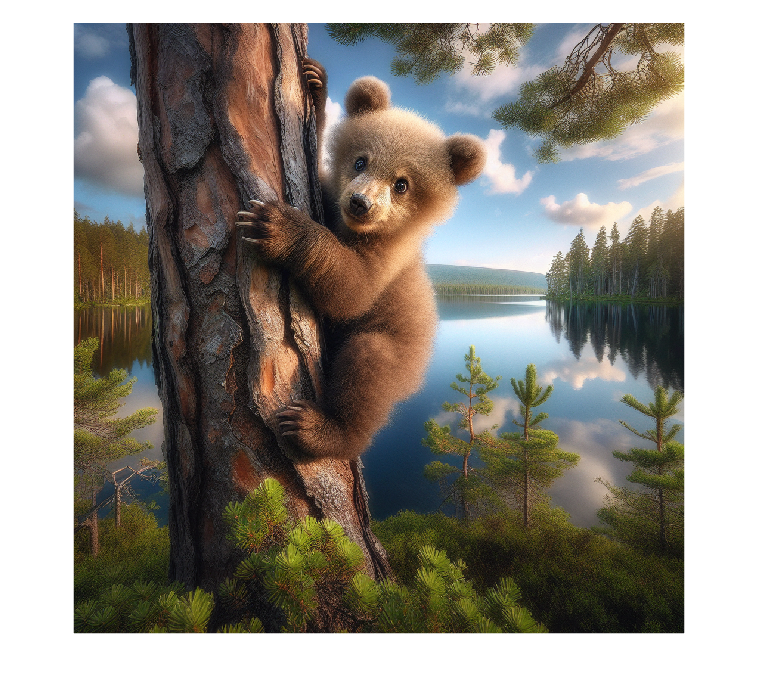

imagePath = fullfile('examples','images','bear.png');
figure
imshow(imagePath)

Benerate variations for that image.

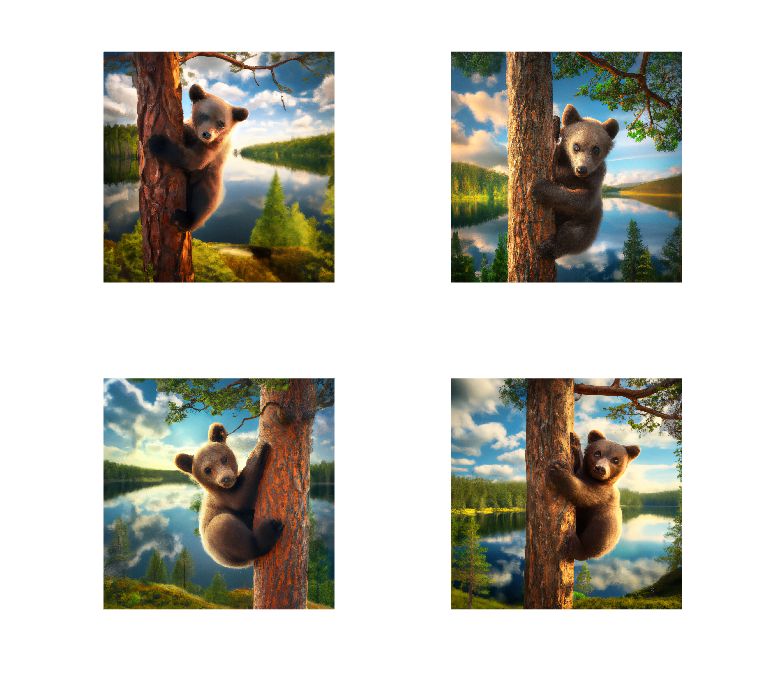

[images,resp] = createVariation(mdl, imagePath, NumImages=4);
if ~isempty(images)
    tiledlayout('flow')
    for ii = 1:numel(images)
        nexttile
        imshow(images{ii})
    end
else
    disp(resp.Body.Data.error)
end

## Edit an Image with DALL·E

Use an image containing a mask to apply modifications to the masked area.

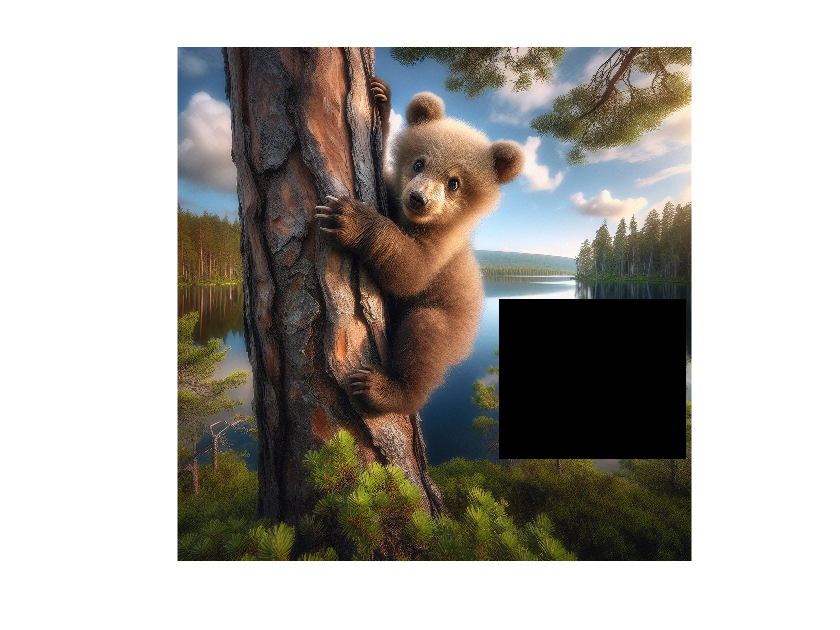

imagePath = fullfile('examples','images','mask_bear.png');
figure
imshow(imagePath)

Add a swan to the masked area using the function edit.

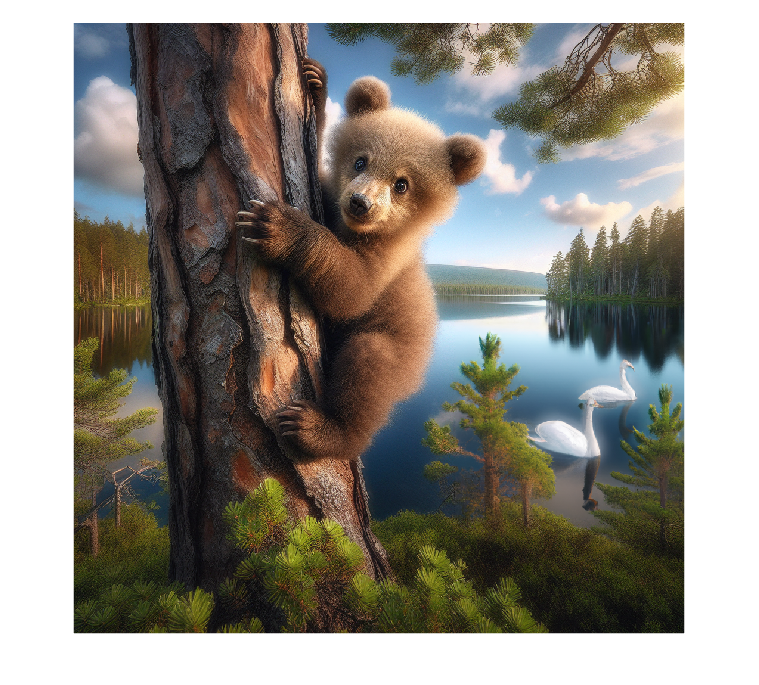

[images,resp] = edit(mdl, imagePath, "Swan", MaskImagePath=maskImagePath);

if isfield(resp.Body.Data,'data')
    figure
    imshow(images{1});
else
    disp(resp.Body.Data.error)
end

*Copyright 2024 The MathWorks, Inc.*